# Basics of Scripting

## Section 1: Navigating Matlab

By default, Matlab is broken into five separate boxes:

**Command window: **Running basic commands, displaying output etc. 

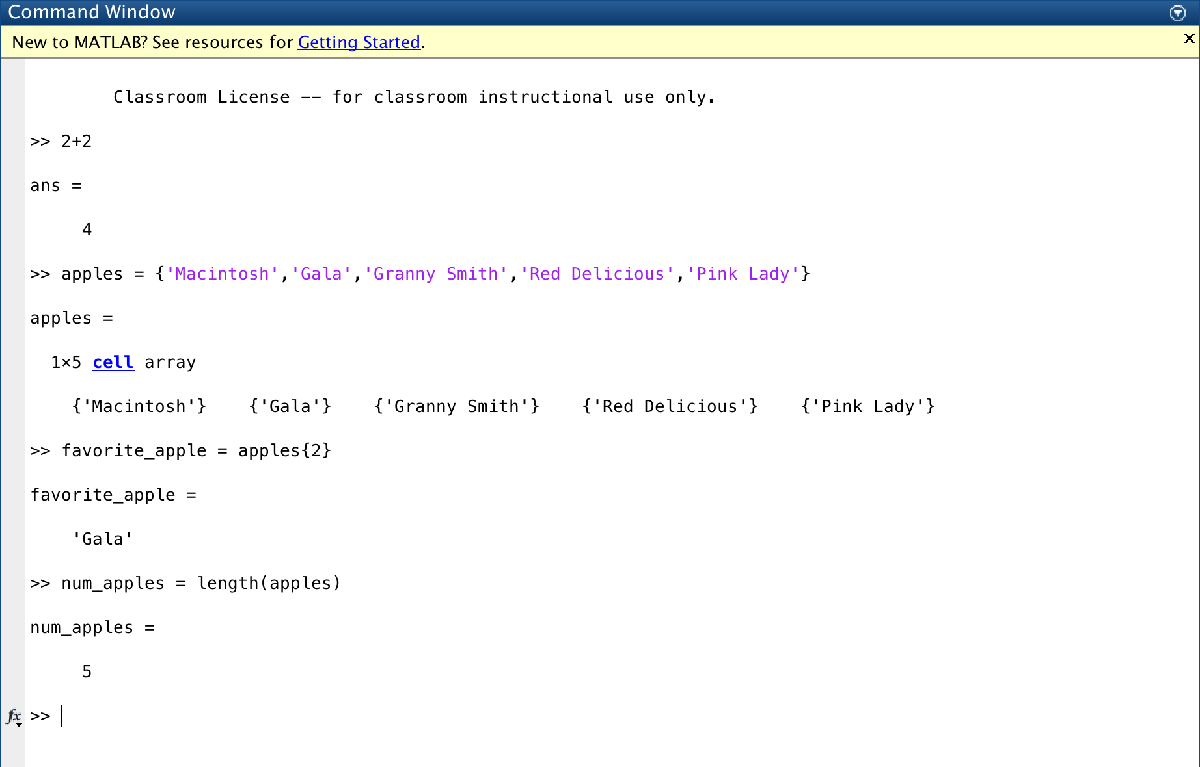

**Workspace: **View variable names, values, types, sizes.

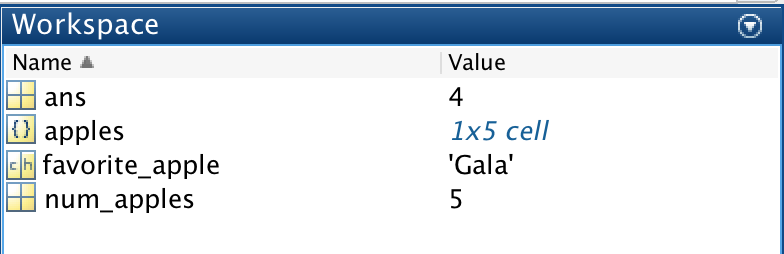

**Editor: **Writing, debugging scripts.

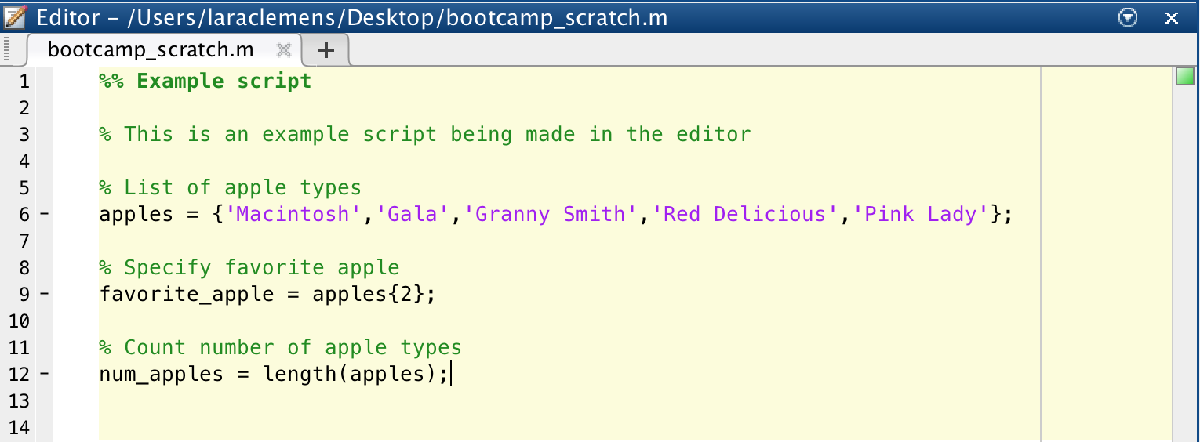

**Current folder: **Folder navigation system. 

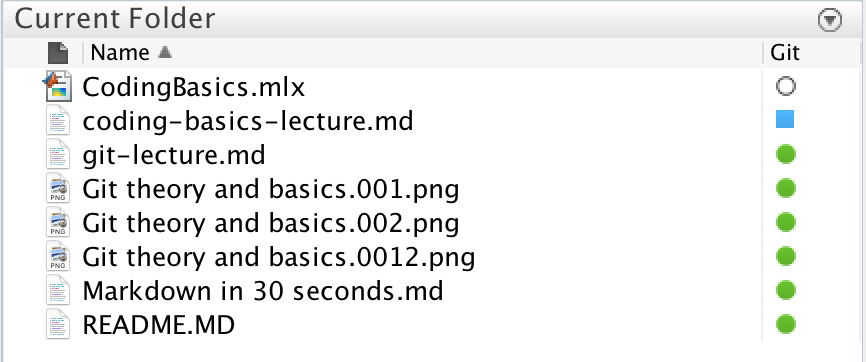

**Details: **View details of script selected in Current Folder window, including section headers.

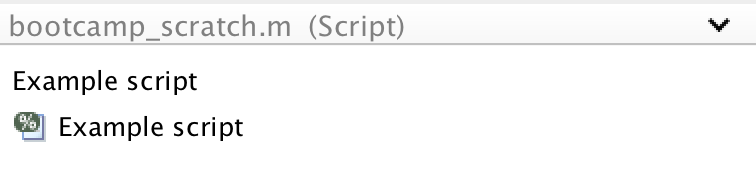

Each of these can be resized, dragged to a new position, or moved to it's own window (undocked). 

You can choose what works for you.

## Section 2: Variables

**Subsection 2.1: Math in the command window**

Working in the command window, try the following:


$$123 + 987$$



$$551/17$$



$$4-6/2$$


(551/17)+sin(551/17)/4 - (551/17)^(-2/3)

**Subsection 2.2: Variables**

Often calculations are simpler if you can store values somewhere. This let's you use the same number multiple times, store values for future use, creates more readable expressions, change a number in a single location rather than everywhere it's used etc

Matlab stores variables with '=':

x = 5

time = 10

n_people = 7.7e9

Variables names always go to the left of the expression:

vel = 4 <- WORKS

4 = vel <- DOES NOT WORK

**Subsection 2.3: Naming variables**

There are some hard rules and some soft rules regarding variable names:

- variable names must begin with a letter (not a number,symbol)

- cannot contain spaces (can use underscores, camel case)

- Note: uppercase and lowercase letters are distinct

Variable names are something you should think a lot about. Some rules of thumb:

- helps to be descriptive (e.g. num_people vs n)

- pick a convention and stick with it (e.g. always starting with lowercase, using all capitals for variables that shouldn't change, etc)

- avoid names of Matlab functions (e.g. sqrt, sin)

Some names are protected by Matlab. These will turn blue before you try to assign it:

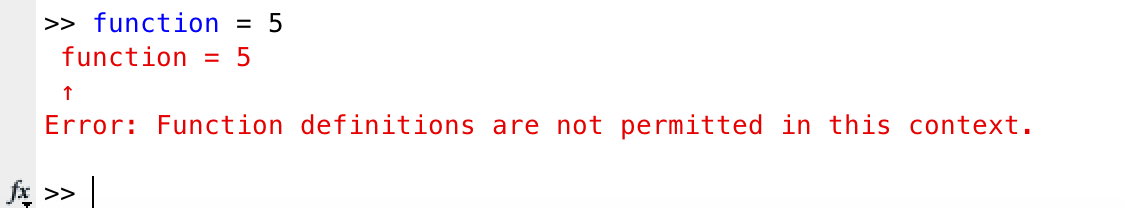

**Subsection 2.4: Clearing variables**

Sometimes it is helpful to clear a variable.

To clear just variables:

Clears all variables: 

clearvars

Clears only those specified: 

clearvars variable1 variable2

To clear more than just variables (see Matlab documentation for [clear](https://www.mathworks.com/help/matlab/ref/clear.html)):

clear (or clear all)

clear variable1 variable2

## Section 3: Scripts, Functions

**Subsection 3.1: Scripts (.m)**

Scripts can be used to save work, run lots of commands at once, debug, create functions, etc.

Scripts are the default file for writing code in Matlab. Scripts simply run what is written. 

All variables are *global, *and are not cleared unless specified by user. 

**Subsection 3.1: Functions (.m)**

Functions can take an input and return an output. Used if a section of code will be used many times. 

All variables defined in the function are *local* and cannot be seen by an encapsulating script. This is generally viewed as safer than the global variables of scripts - they won't get overwritten, used unexpectedly etc.

**Subsection 3.2: Live scripts (.mlx)**

Live scripts (like this one) can be used to include plain text, latex equations, and images along with the code. It will also display output in-line or to the side when each section is run.

This is particularly useful for documentation and teaching. 

Drawbacks of live scripts:

- They are slower than plain scripts.

- Github, git reads the live script as a binary file - it will not show you line-by-line changes.

- Still new - older Matlab versions limit capabilities, making sharing with collaborators harder.

## Section 4: If Statements

If statements are a way to do something conditionally.

## Section 5: For Loops

## Section 6: While Loops

## Section 7: Vectors, Matrices, Indexing

## Section 8: Plotting

Visualizing data and functions is important for explaining and understanding models, results, and trends. Matlab has a very basic way to plot:

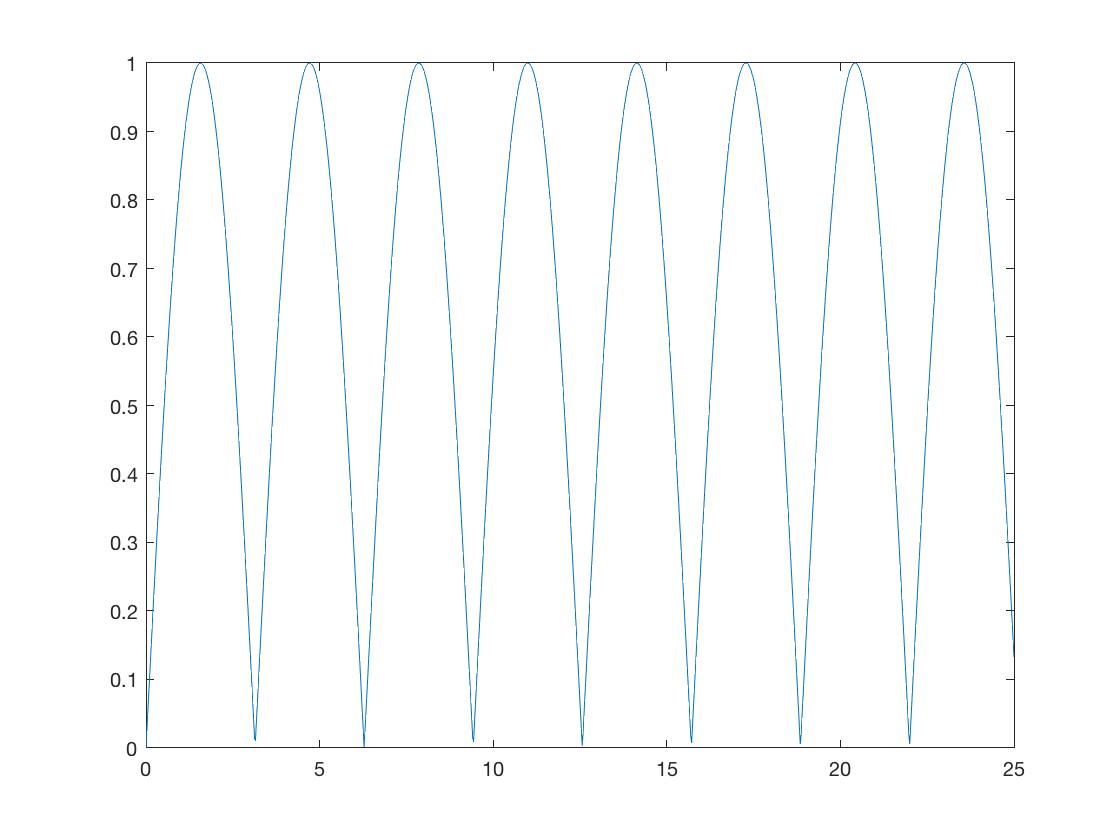

% create some data to plot
x_data = linspace(0,25,1000);
y_data = abs(sin(x_data));

% plot
figure;
plot(x_data,y_data);

How can we make this plot nicer?

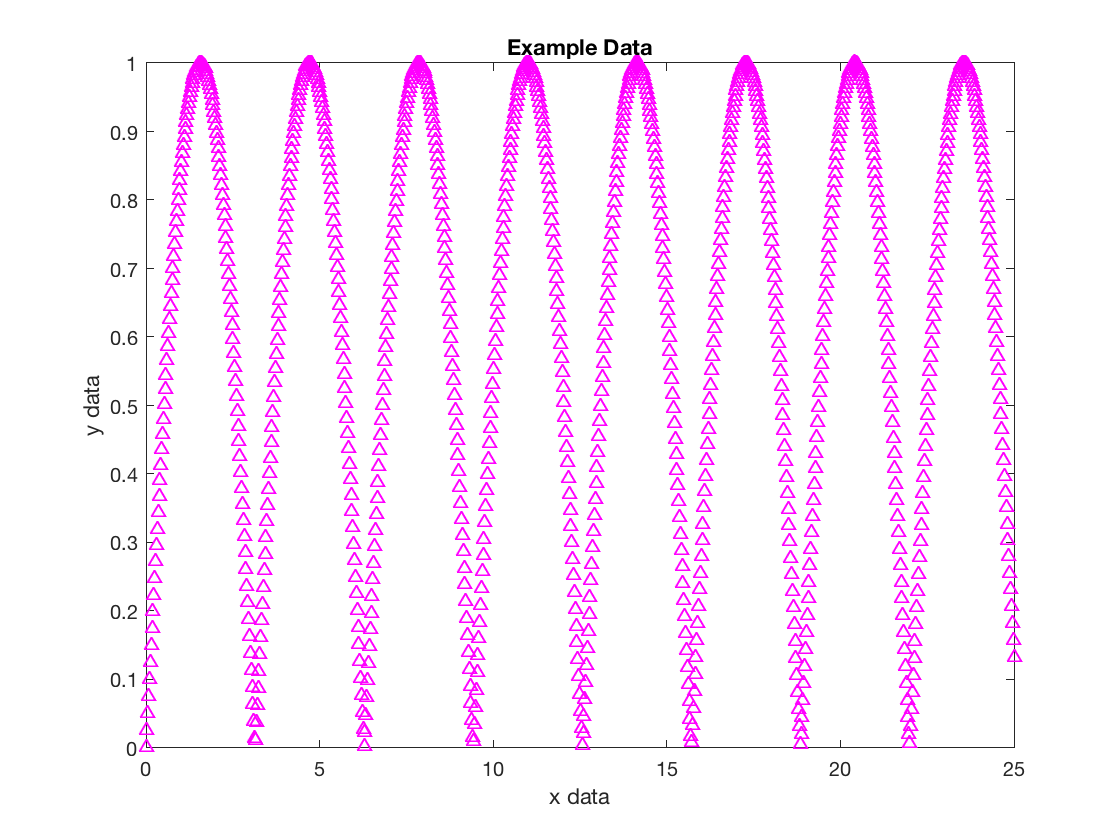

figure('Name','Example data'); 
plot(x_data,y_data,'^m'); % ^ denotes a possible marker style (triangles), m indicates preset color (magenta)
xlabel('x data');
ylabel('y data');
title('Example Data');

What about plotting multiple datasets on the same graph?

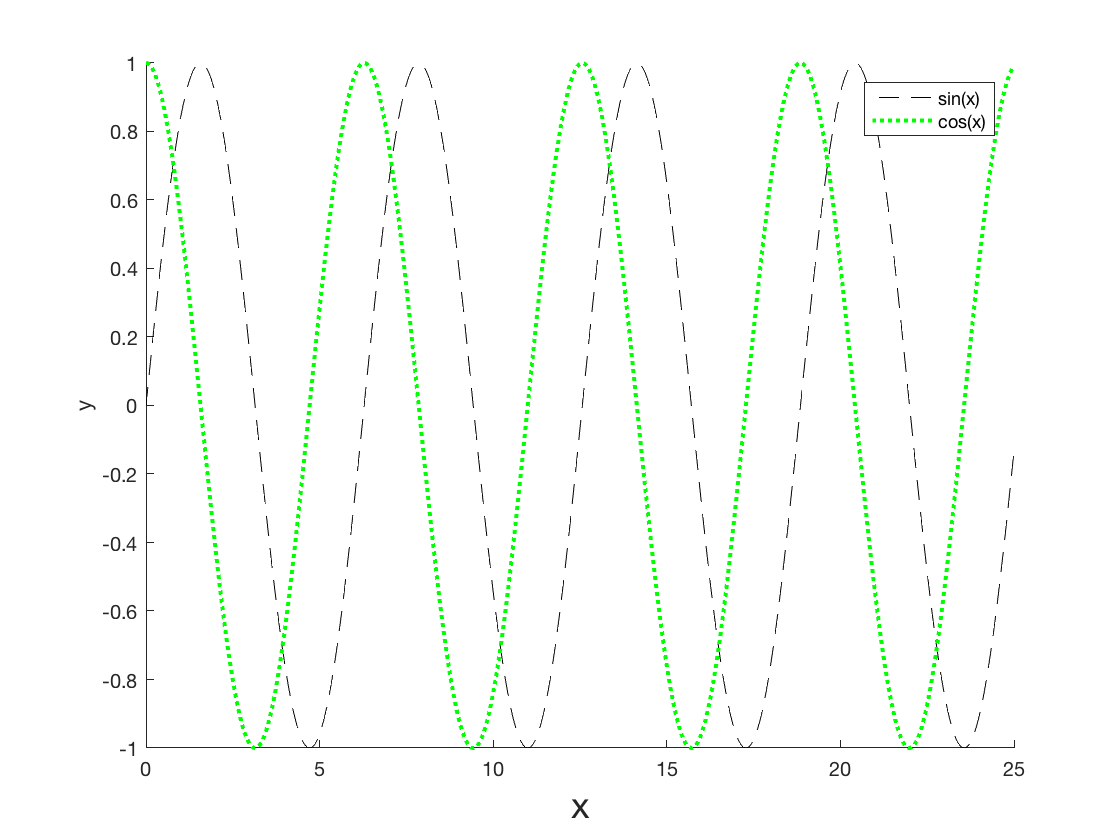

% plot sin(x), cos(x) on same axes
figure('Name','Sin(x) and Cos(x)'); hold on; 
pSin = plot(x_data,sin(x_data),'LineStyle','--','Color','k'); % could equivalently write plot(x_data,sin(x_data),'--k');
pCos = plot(x_data,cos(x_data),':g');
pCos.LineWidth = 2; % could use 'LineWidth',2 in plot() instead
xlabel('x','FontSize',18);
ylabel('y');
legend('sin(x)','cos(x)');

The command '[hold](https://www.mathworks.com/help/matlab/ref/hold.html) on' means any new plots will end up on same figure without overwriting. This will continue until 'hold off' is called, or until a new figure is called.

Assigning a plot to a variable is called a 'plot handle'. You can make many manipulations after the fact if you've saved the plot handle. It's also an alternate way to make property changes without having a very long single line of code. Similarly, you can save figure or axes handles.

Figures in Matlab are infinitely customizable with varying levels of ease.

Some other helpful ways to customize:

- xlim, ylim - set limits for axes

- xtick, ytick - set where axes ticks should occur

- set Position - set position on screen and size of a figure or axes within a figure

- [List of line properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html)

- [List of axes properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.axis.axes-properties.html)

There are many other [types of plots](https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html) that are useful:

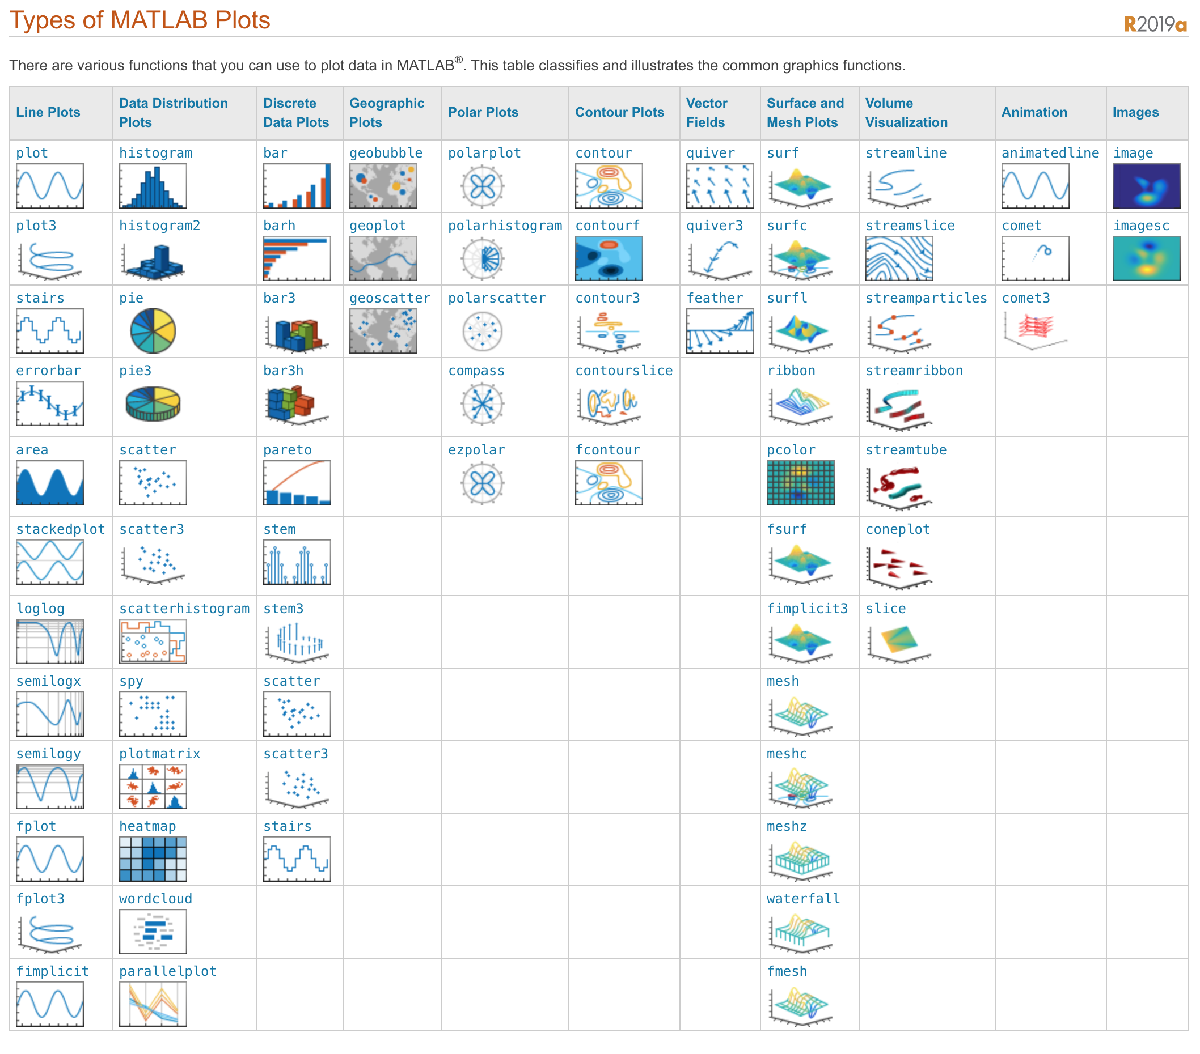

## Section 9: Save, Load

## Section 10: Debugging

Some tips 

## Section 11: Google is your friend.